# Mean Activity

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze

Prefix_1 = '2020-02-23-optoknirps_new_embryo7'; % Y->N
Prefix_2 = '2020-03-04-optoknirps_new_embryo10'; % N->Y

Variables depending on the data

- Start/Final frames

% Y->N: embryo7
start_frame_1 = 55;
final_frame_1 = 157;

% N->Y
start_frame_2 = 10;
final_frame_2 = 120;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/'];

mkdir(FigPath)

% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledNuclei dataset
LoadComNucleiPath_1 = [DynamicsResultsFolder '/' Prefix_1 '/CompiledNuclei.mat']; 
LoadComNucleiPath_2 = [DynamicsResultsFolder '/' Prefix_2 '/CompiledNuclei.mat']; 

data.nuclei_1 = load(LoadComNucleiPath_1);
data.nuclei_2 = load(LoadComNucleiPath_2);

ElapsedTime_1 = data.nuclei_1.ElapsedTime-data.nuclei_1.ElapsedTime(start_frame_1);
ElapsedTime_2 = data.nuclei_2.ElapsedTime-data.nuclei_2.ElapsedTime(start_frame_2);
Time_1 = ElapsedTime_1(start_frame_1:final_frame_1);
Time_2 = ElapsedTime_2(start_frame_2:final_frame_2);

APbinID = data.nuclei_1.APbinID;

## Draw figures for nuclei

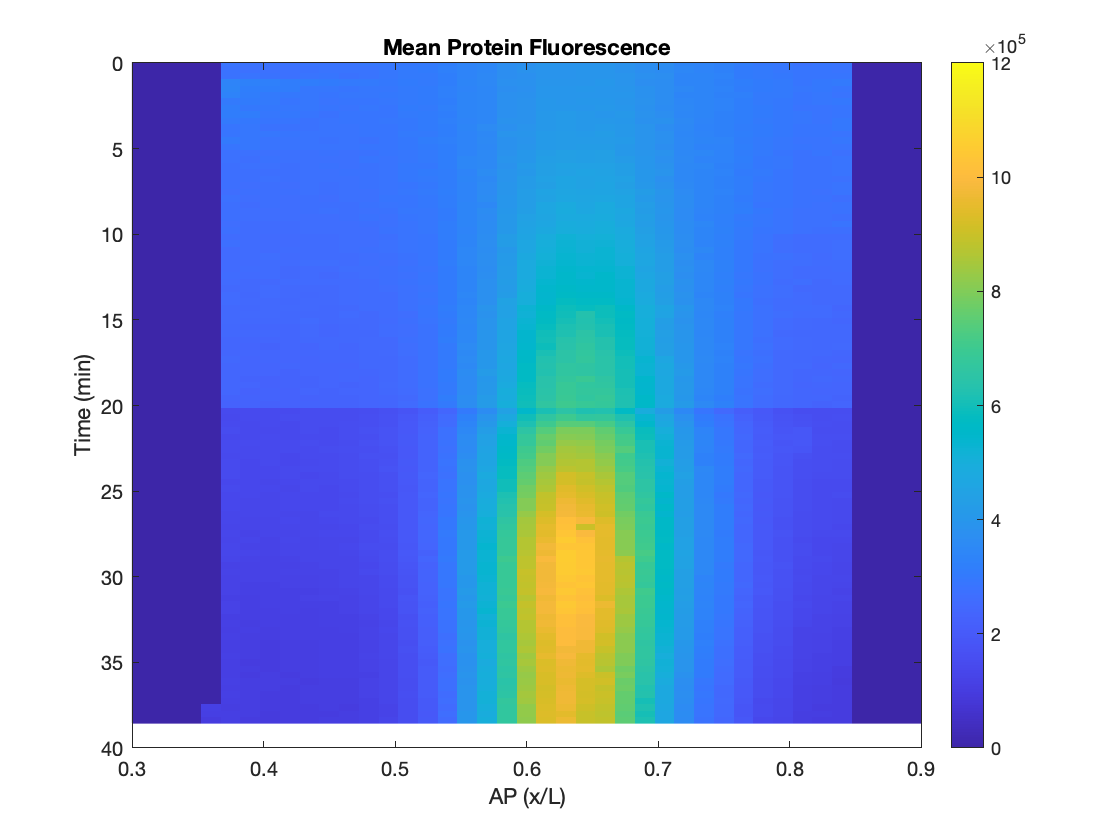

data_plot_1 = data.nuclei_1.MeanVectorAP;
data_plot_2 = data.nuclei_2.MeanVectorAP;

MeanNucleiFig = figure;
imagesc(APbinID,Time_1,data_plot_1(start_frame_1:final_frame_1,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])
ylim([0 40])
colorbar
caxis([0 12E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo_1.pdf' ]);

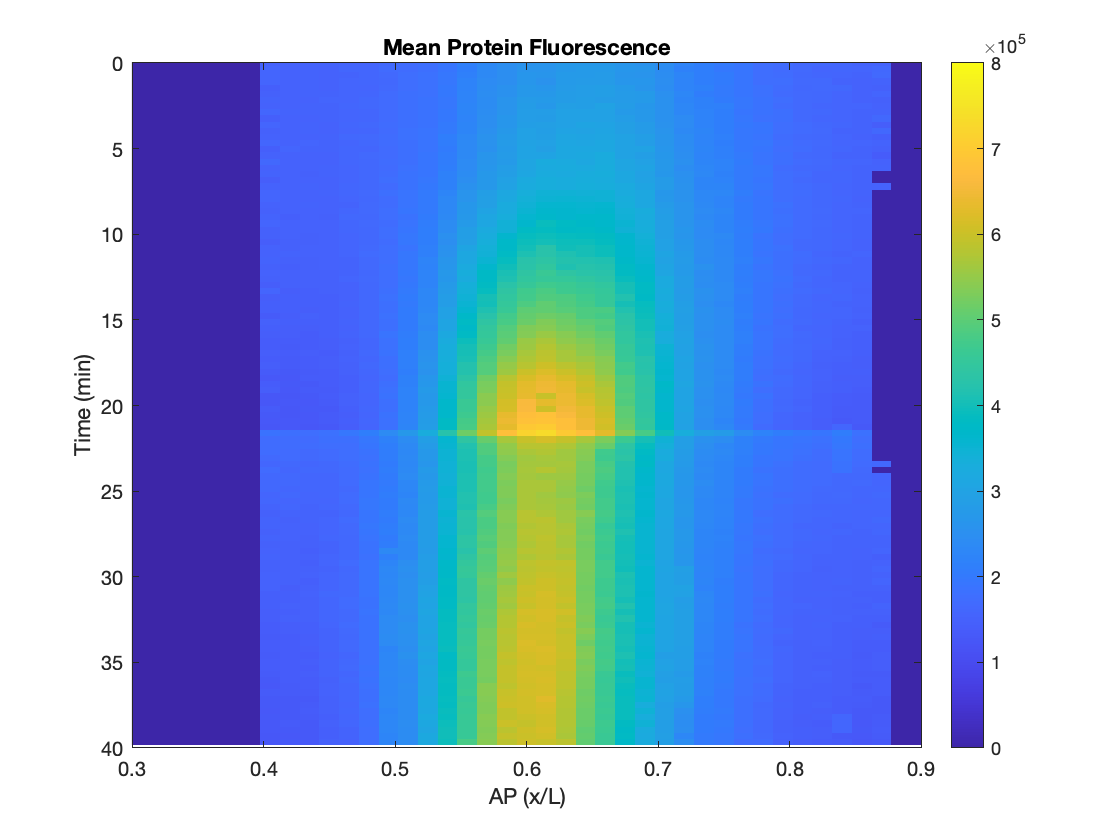


MeanNucleiFig = figure;
imagesc(APbinID,Time_2,data_plot_2(start_frame_2:final_frame_2,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])
ylim([0 40])
colorbar
caxis([0 8E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo_2.pdf' ]);

## Plot them both together

Plot for bin 40-...

%{
%for i = 39:47
for i = 28:58
   
    APbin_temp = i;
    protein_temp_1 = data.nuclei_1.MeanVectorAP(start_frame_1:final_frame_1,APbin_temp);
    protein_temp_2 = data.nuclei_2.MeanVectorAP(start_frame_2:final_frame_2,APbin_temp);
    
    OverlayFig = figure;
    xlabel('Time (min)')
    title(['Mean Activity for x = ' num2str(APbinID(APbin_temp))])
    plot(Time_1,protein_temp_1)
    hold on
    plot(Time_2,protein_temp_2)
    hold off
    xlabel('Time (min)')
    ylabel('Protein Concentration (AU)')
    ylim([0E5 12E5])
    
    saveas(OverlayFig,[FigPath '/calib_traces/bin_' num2str(i) '.pdf'])
    end
    %}

## Plot at boundary position

Anterior boundary

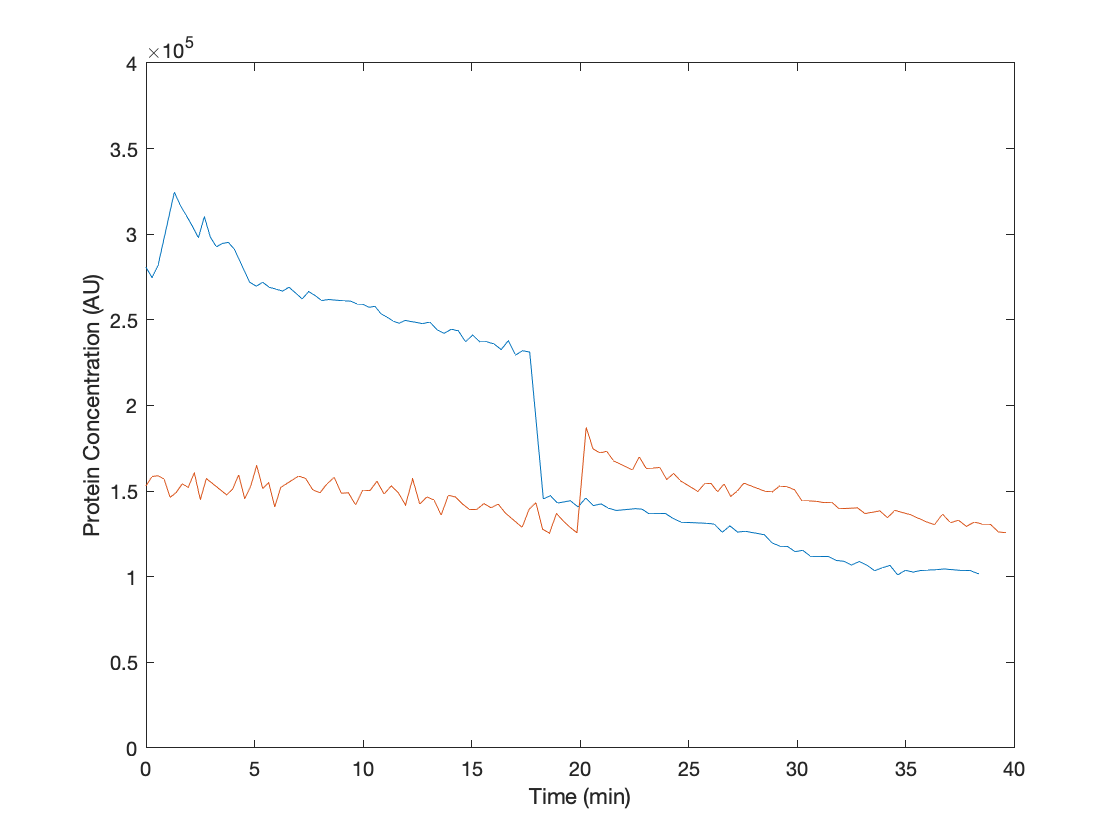

APbin_ant_1 = 27;
APbin_ant_2 = 28;
protein_temp_1 = data.nuclei_1.MeanVectorAP(start_frame_1:final_frame_1,APbin_ant_1);
protein_temp_2 = data.nuclei_2.MeanVectorAP(start_frame_2:final_frame_2,APbin_ant_2);

OverlayFig = figure;
xlabel('Time (min)')
plot(Time_1,protein_temp_1)
hold on
plot(Time_2,protein_temp_2)
hold off
xlabel('Time (min)')
ylabel('Protein Concentration (AU)')
ylim([0E5 4E5])

saveas(OverlayFig,[FigPath '/calib_traces/anterior_calib.pdf'])

Posterior boundary

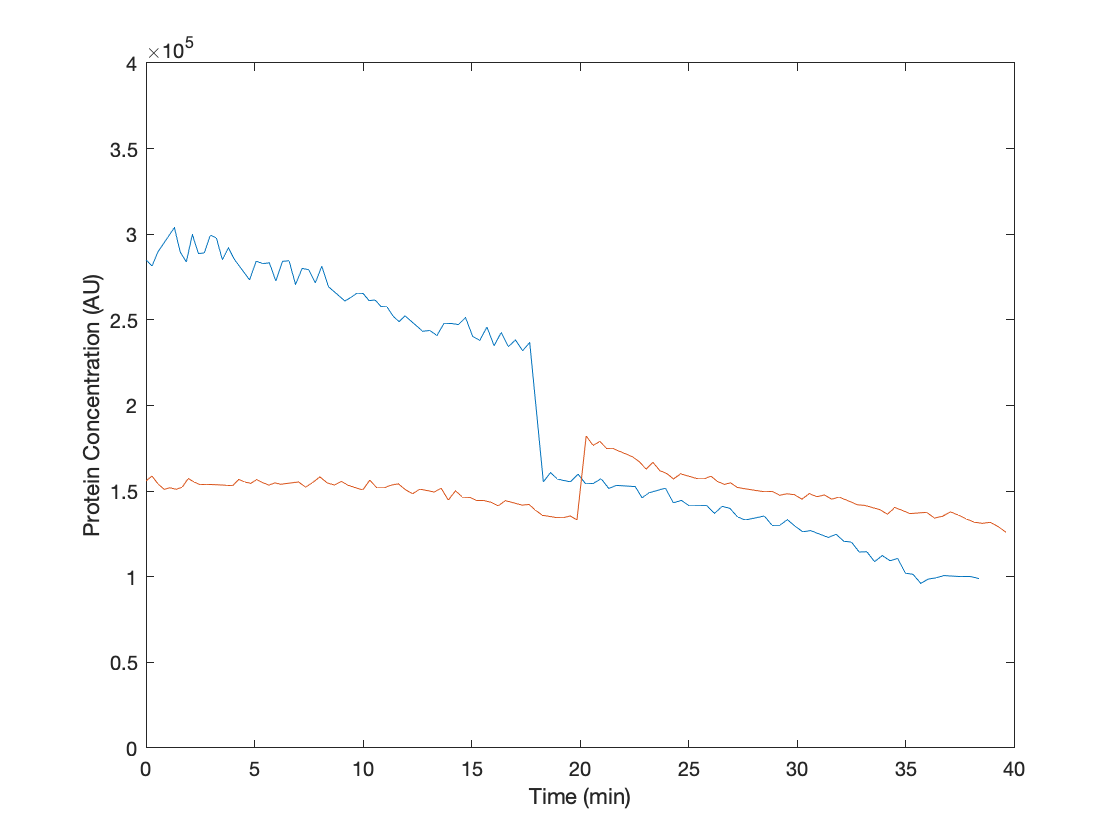

APbin_ant_1 = 57;
APbin_ant_2 = 58;
protein_temp_1 = data.nuclei_1.MeanVectorAP(start_frame_1:final_frame_1,APbin_ant_1);
protein_temp_2 = data.nuclei_2.MeanVectorAP(start_frame_2:final_frame_2,APbin_ant_2);

OverlayFig = figure;
xlabel('Time (min)')
plot(Time_1,protein_temp_1)
hold on
plot(Time_2,protein_temp_2)
hold off
xlabel('Time (min)')
ylabel('Protein Concentration (AU)')
ylim([0E5 4E5])

saveas(OverlayFig,[FigPath '/calib_traces/posterior_calib.pdf'])

## Calculate correction factor

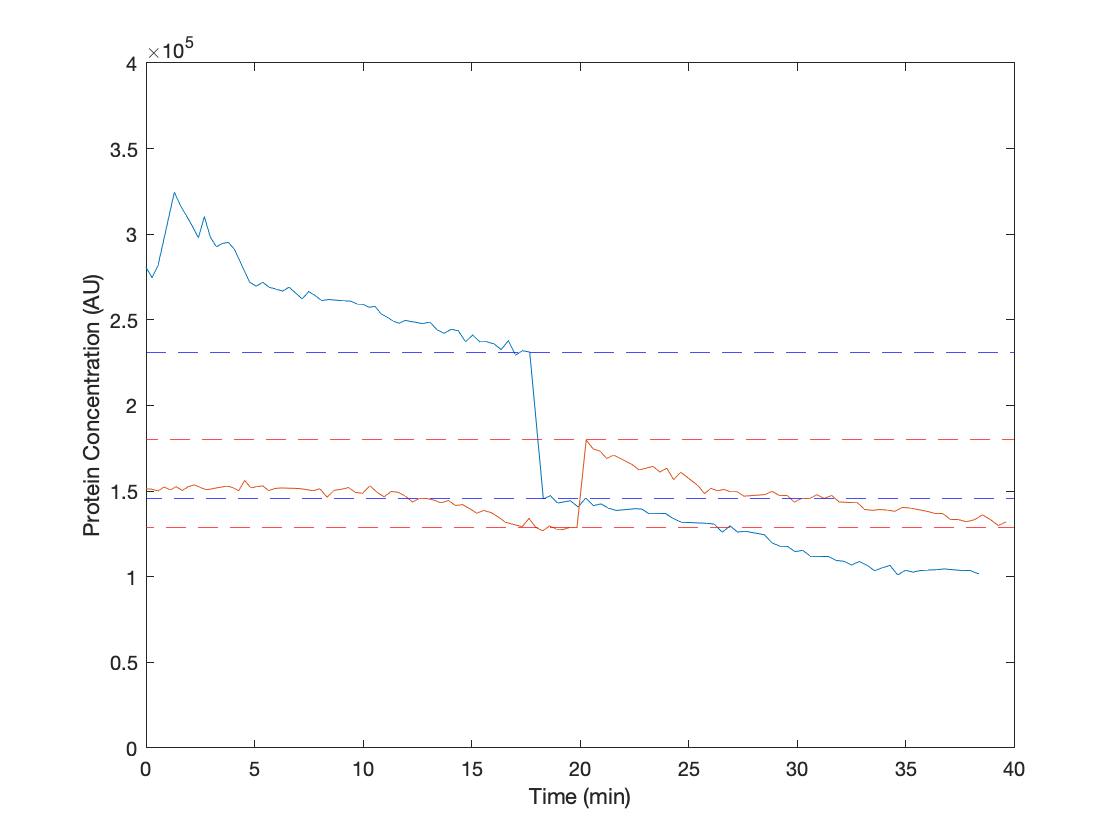

APbin_ant_1 = 27;
APbin_ant_2 = 29;
protein_temp_1 = data.nuclei_1.MeanVectorAP(start_frame_1:final_frame_1,APbin_ant_1);
protein_temp_2 = data.nuclei_2.MeanVectorAP(start_frame_2:final_frame_2,APbin_ant_2);

OverlayFig = figure;
xlabel('Time (min)')
plot(Time_1,protein_temp_1)
hold on
plot(Time_2,protein_temp_2)
yline(231200,'b--')
yline(145500,'b--')
yline(179900,'r--')
yline(128700,'r--')
hold off
xlabel('Time (min)')
ylabel('Protein Concentration (AU)')
ylim([0E5 4E5])

saveas(OverlayFig,[FigPath '/calib_traces/anterior_calib_with_ref.pdf'])

Then, we can calculate the factors

a_b_1ant = (2312-1455)/1455/2.5

a_b_1ant = 0.2356

a_b_2ant = (1799-1287)/1287/2

a_b_2ant = 0.1989

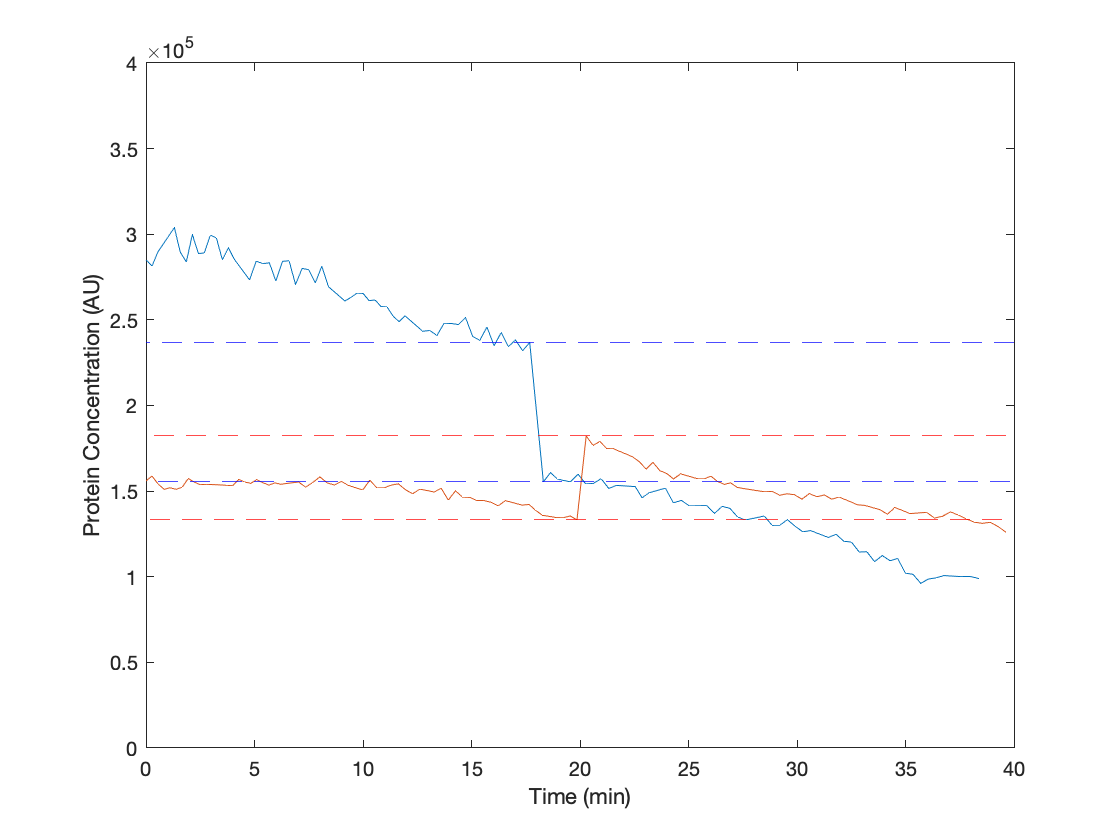

APbin_ant_1 = 57;
APbin_ant_2 = 58;

time_perturbation_1 = 54;
time_perturbation_2 = 60;

protein_temp_1 = data.nuclei_1.MeanVectorAP(start_frame_1:final_frame_1,APbin_ant_1);
protein_temp_2 = data.nuclei_2.MeanVectorAP(start_frame_2:final_frame_2,APbin_ant_2);

OverlayFig = figure;
xlabel('Time (min)')
plot(Time_1,protein_temp_1)
hold on
plot(Time_2,protein_temp_2)
yline(236800,'b--')
yline(155400,'b--')
yline(182200,'r--')
yline(133200,'r--')
hold off
xlabel('Time (min)')
ylabel('Protein Concentration (AU)')
ylim([0E5 4E5])


saveas(OverlayFig,[FigPath '/calib_traces/posterior_calib_with_ref.pdf'])

a_b_1pos = 814/1554/2.5

a_b_1pos = 0.2095

a_b_2pos = 492/1332/2

a_b_2pos = 0.1847

mean([a_b_1ant,a_b_1pos,a_b_2ant,a_b_2pos])

ans = 0.2072